Ground truth

%% time 
t = kinematic.time();

%% ground truth data 
x_gt     = out.groundTruth.signals.values(:,1);
y_gt     = out.groundTruth.signals.values(:,2);
z_gt     = out.groundTruth.signals.values(:,3);
phi_gt   = out.groundTruth.signals.values(:,4);
theta_gt = out.groundTruth.signals.values(:,5);
psi_gt   = out.groundTruth.signals.values(:,6);

dx_gt     = out.velocities.signals.values(:,1);
dy_gt     = out.velocities.signals.values(:,2);
dz_gt     = out.velocities.signals.values(:,3);
dphi_gt   = out.velocities.signals.values(:,4);
dtheta_gt = out.velocities.signals.values(:,5);
dpsi_gt   = out.velocities.signals.values(:,6);


EKF Data 

%% ekf 
x_ekf = kinematic.state(1,:);
y_ekf = kinematic.state(2,:);
z_ekf = kinematic.state(3,:);

dx_ekf = kinematic.state(4,:);
dy_ekf = kinematic.state(5,:);
dz_ekf = kinematic.state(6,:);

ddx_ekf = kinematic.state(7,:);
ddy_ekf = kinematic.state(8,:);
ddz_ekf = kinematic.state(9,:);

phi_ekf = kinematic.state(10,:);
theta_ekf = kinematic.state(11,:);
psi_ekf = kinematic.state(12,:);

dphi_ekf = kinematic.state(13,:);
dtheta_ekf = kinematic.state(14,:);
dpsi_ekf = kinematic.state(15,:);

ddphi_ekf = kinematic.state(16,:);
ddtheta_smooth = kinematic.state(17,:);
ddpsi_ekf = kinematic.state(18,:);

Smoother data 


%% ekf 
x_smooth = xSmooth(1,:);
y_smooth = xSmooth(2,:);
z_smooth = xSmooth(3,:);

dx_smooth = xSmooth(4,:);
dy_smooth = xSmooth(5,:);
dz_smooth = xSmooth(6,:);

ddx_smooth = xSmooth(7,:);
ddy_smooth = xSmooth(8,:);
ddz_smooth = xSmooth(9,:);

phi_smooth = xSmooth(10,:);
th_smooth = xSmooth(11,:);
psi_smooth = xSmooth(12,:);

dphi_smooth = xSmooth(13,:);
dth_smooth = xSmooth(14,:);
dpsi_smooth = xSmooth(15,:);

ddphi_smooth = xSmooth(16,:);
ddth_smooth = xSmooth(17,:);
ddpsi_smooth = xSmooth(18,:);


EKF PLOTS

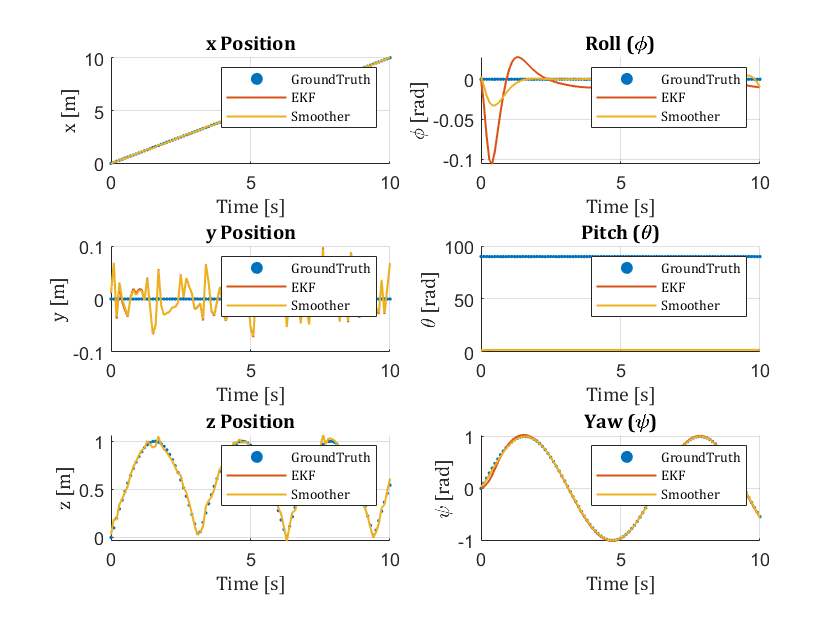

%% plot EKF 
sz = 3;
figure()
subplot(3,2,1)
scatter(t,x_gt, sz, 'filled')
hold on
plot(t,x_ekf, 'LineWidth',1)
hold on
plot(t,x_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'x [m]'},'FontSize',8,'FontName','Cambria');
title({'x Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,3)
scatter(t,y_gt, sz, 'filled')
hold on
plot(t,y_ekf, 'LineWidth',1)
hold on
plot(t,y_smooth,'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'y [m]'},'FontSize',8,'FontName','Cambria');
title({'y Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,5)
scatter(t,z_gt, sz, 'filled')
hold on
plot(t,z_ekf, 'LineWidth',1)
hold on
plot(t,z_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'z [m]'},'FontSize',8,'FontName','Cambria');
title({'z Position'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,2)
scatter(t,phi_gt, sz, 'filled')
hold on
plot(t,phi_ekf, 'LineWidth',1)
hold on
plot(t,phi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\phi [rad]'},'FontSize',8,'FontName','Cambria');
title({'Roll (\phi)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,4)
scatter(t,theta_gt, sz, 'filled')
hold on
plot(t,theta_ekf, 'LineWidth',1)
hold on
plot(t,th_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\theta [rad]'},'FontSize',8,'FontName','Cambria');
title({'Pitch (\theta)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,6)
scatter(t,psi_gt, sz, 'filled')
hold on
plot(t,psi_ekf, 'LineWidth',1)
hold on
plot(t,psi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'\psi [rad]'},'FontSize',8,'FontName','Cambria');
title({'Yaw (\psi)'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

derivatives

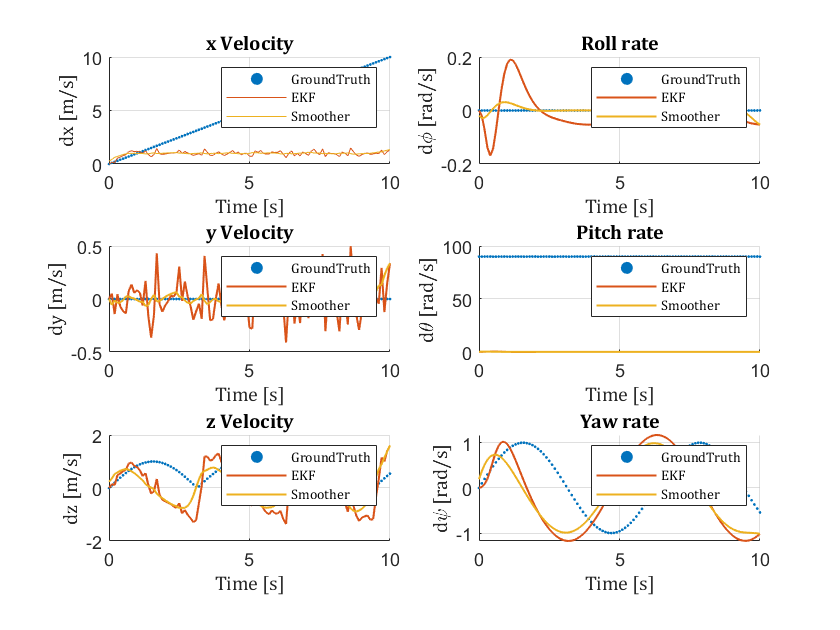

sz = 2;
figure()
subplot(3,2,1)
scatter(t,dx_gt, sz, 'filled')
hold on
plot(t,dx_ekf)
hold on
plot(t,dx_smooth)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dx [m/s]'},'FontSize',8,'FontName','Cambria');
title({'x Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,3)
scatter(t,y_gt, sz, 'filled')
hold on
plot(t,dy_ekf, 'LineWidth',1)
hold on
plot(t,dy_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dy [m/s]'},'FontSize',8,'FontName','Cambria');
title({'y Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,5)
scatter(t,dz_gt, sz, 'filled')
hold on
plot(t,dz_ekf, 'LineWidth',1)
hold on
plot(t,dz_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'dz [m/s]'},'FontSize',8,'FontName','Cambria');
title({'z Velocity'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,2)
scatter(t,dphi_gt, sz, 'filled')
hold on
plot(t,dphi_ekf, 'LineWidth',1)
hold on
plot(t,dphi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\phi [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Roll rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,4)
scatter(t,dtheta_gt, sz, 'filled')
hold on
plot(t,dtheta_ekf, 'LineWidth',1)
hold on
plot(t,dth_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\theta [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Pitch rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

subplot(3,2,6)
scatter(t,dpsi_gt, sz, 'filled')
hold on
plot(t,dpsi_ekf, 'LineWidth',1)
hold on
plot(t,dpsi_smooth, 'LineWidth',1)
hold on

xlabel({'Time [s]'},'FontSize',8,'FontName','Cambria');
ylabel({'d\psi [rad/s]'},'FontSize',8,'FontName','Cambria');
title({'Yaw rate'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

3d trajectory

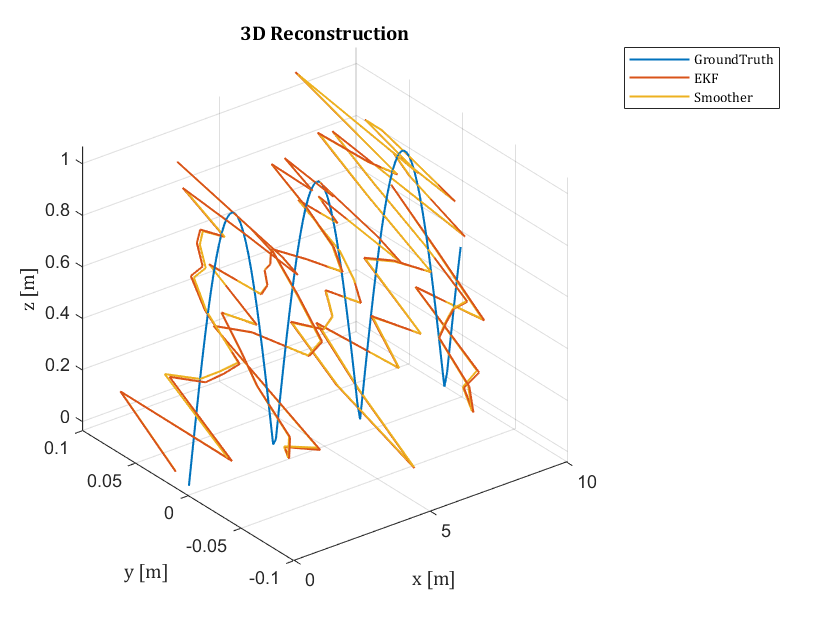

figure()
plot3(x_gt, y_gt, z_gt, 'LineWidth',1)
hold on
plot3(x_ekf, y_ekf, z_ekf, 'LineWidth',1)
hold on
plot3(x_smooth, y_smooth, z_smooth, 'LineWidth',1)
xlabel({'x [m]'},'FontSize',8,'FontName','Cambria');
ylabel({'y [m]'},'FontSize',8,'FontName','Cambria');
zlabel({'z [m]'},'FontSize',8,'FontName','Cambria');
title({'3D Reconstruction'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
%zlim([0,1.5])
%ylim([-0.5,0.5])
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

2D ground plot

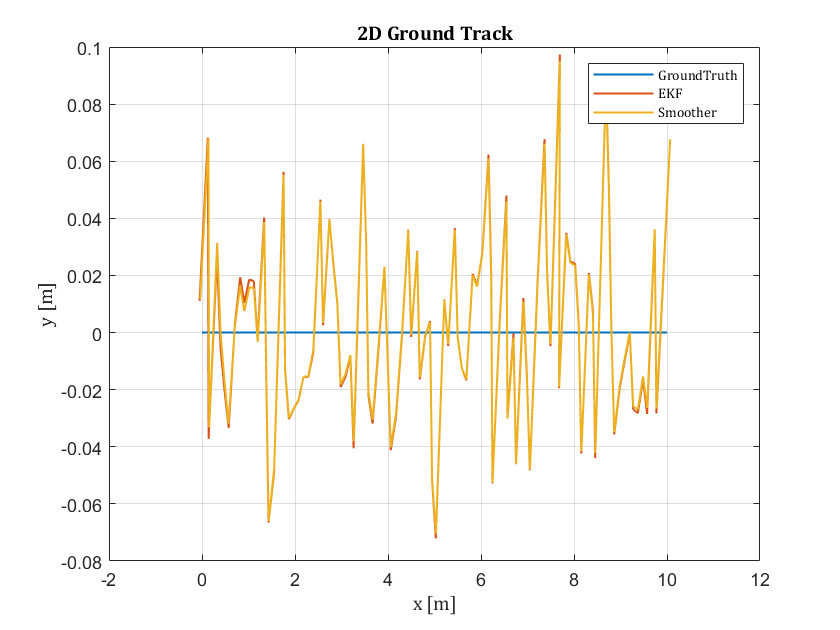

figure()
plot(x_gt, y_gt, 'LineWidth',1 )
hold on
plot(x_ekf, y_ekf, 'LineWidth',1)
hold on
plot(x_smooth, y_smooth, 'LineWidth',1)
xlabel({'x [m]'},'FontSize',8,'FontName','Cambria');
ylabel({'y [m]'},'FontSize',8,'FontName','Cambria');
zlabel({'z [m]'},'FontSize',8,'FontName','Cambria');
title({'2D Ground Track'},'FontWeight','bold','FontSize',12,...
    'FontName','Cambria');
grid on
ax = gca;
ax.FontSize =9; 
%ylim([-0.3,0.3])
%xlim([0,10])
legend({'GroundTruth','EKF','Smoother'},'FontSize',7,'FontName','Cambria')

RMS error EKF


x_rms_ekf = sqrt(mean((x_gt(:)-x_ekf(:)).^2))

x_rms_ekf = 0.0335

y_rms_ekf = sqrt(mean((y_gt(:)-y_ekf(:)).^2))

y_rms_ekf = 0.0335

z_rms_ekf = sqrt(mean((z_gt(:)-z_ekf(:)).^2))

z_rms_ekf = 0.0340


% dx_rms_ekf = sqrt(mean((dx_gt(:)- dx_ekf(:)).^2))
% dy_rms_ekf = sqrt(mean((dy_gt(:)- dy_ekf(:)).^2))
% dz_rms_ekf = sqrt(mean((dz_gt(:)- dz_ekf(:)).^2))

xyz_ekf = [x_rms_ekf, y_rms_ekf, z_rms_ekf];
rms_xyz_ekf = rms(xyz_ekf)

rms_xyz_ekf = 0.0337



phi_rms_ekf = sqrt(mean((phi_gt(:)-phi_ekf(:)).^2))

phi_rms_ekf = 0.0223

th_rms_ekf = sqrt(mean((theta_gt(:)-theta_ekf(:)).^2))

th_rms_ekf = 87.9756

psi_rms_ekf = sqrt(mean((psi_gt(:)-psi_ekf(:)).^2))

psi_rms_ekf = 0.0296


r_ekf = [phi_rms_ekf, th_rms_ekf, psi_rms_ekf];
rms_r_ekf = rms(r_ekf)

rms_r_ekf = 50.7928



% dphi_rms_ekf = sqrt(mean((dphi_gt(:)-dphi_ekf(:)).^2))
% dth_rms_ekf = sqrt(mean((dtheta_gt(:)-dtheta_ekf(:)).^2))
% dpsi_rms_ekf = sqrt(mean((dpsi_gt(:)-dpsi_ekf(:)).^2))

RMS error Smoother


x_rms_sm = sqrt(mean((x_gt(:)-x_smooth(:)).^2))

x_rms_sm = 0.0328

y_rms_sm = sqrt(mean((y_gt(:)-y_smooth(:)).^2))

y_rms_sm = 0.0329

z_rms_sm = sqrt(mean((z_gt(:)-z_smooth(:)).^2))

z_rms_sm = 0.0335


xyz_smooth = [x_rms_sm, y_rms_sm, z_rms_sm];
rms_xyz_smooth = rms(xyz_smooth)

rms_xyz_smooth = 0.0330


% dx_rms_sm = sqrt(mean((dx_gt(:)- dx_smooth(:)).^2))
% dy_rms_sm = sqrt(mean((dy_gt(:)- dy_smooth(:)).^2))
% dz_rms_sm = sqrt(mean((dz_gt(:)- dz_smooth(:)).^2))

phi_rms_sm = sqrt(mean((phi_gt(:)-phi_smooth(:)).^2))

phi_rms_sm = 0.0080

th_rms_sm = sqrt(mean((theta_gt(:)-th_smooth(:)).^2))

th_rms_sm = 87.9736

psi_rms_sm = sqrt(mean((psi_gt(:)-psi_smooth(:)).^2))

psi_rms_sm = 0.0100


r_smooth = [phi_rms_sm, th_rms_sm, psi_rms_sm];
rms_r_smooth = rms(r_smooth)

rms_r_smooth = 50.7916


% % dphi_rms_sm = sqrt(mean((dphi_gt(:)-dphi_smooth(:)).^2))
% % dth_rms_sm = sqrt(mean((dtheta_gt(:)-dth_smooth(:)).^2))
% % dpsi_rms_sm = sqrt(mean((dpsi_gt(:)-dpsi_smooth(:)).^2))
